# Connect and sample data from a Hokuyo URG-40LX Laser scanner

The widely available Hokuyo URG-04KX LiDAR sensors are the robotics world low-cost planar range sensors of chocie. Rather than giving the robot a single range measurement over a short range, the Hokuyo LiDAR will allow 250 polar range measurements, within a single plane, over a 10m range.

Before running this code please check what USB comport your LiDAR is plugged into and then run the UrgBenriPlsuV.2.0 Hokuyo viewer to make sure the LiDARs fully operational and wasn't left in a jammed state. 

You can run code sequentially, section by section, but beware backing up or running sections out of sequence! Serial ports are tricky beasts and don't  like it if you don't open and close them carefully 

Original code Copyright The MathWorks, Inc 2019. This code has been heavily modified 2-4-2022 to support Olin Fun-Robo Lidar Lab by D. Barrett

disp("progam running") % Indicate lidar code starts ok 

progam running


% Due to the complexity of talking with the Hokuyo over a Windows 10 serial
% link, parts of this code are a bit wonky and somtimes throws some
% non-fatal errors when running. We will turn off error warnings for now
% till course staff or students can find and fix this. 
warning('off','all'); % Temporarily turn MATLAB warnings off

% LiDAR is contained in a Matlab serial object, we need to clean up any old
% lidar objects in the work space to prevent conflicts when creating a new
% one. Search for and delete old ones. For FunRobo, don't owrry about what
% an object is for now, just treat it like a big fancy function. 
serialObjs = instrfind; % Read instrument objects from memory to MATLAB workspace 
if ~isempty(serialObjs) % If there are old objects close to them 
    fclose(serialObjs); % close serial port attached to old lidar
    delete(serialObjs); % delete old lidar objects
end 

% The following code clears up MATLAB workspace of any old work that might
% conflict with your active code
clear 
clc

### Specify which serial port (USB) you have the test bench Hokuyo Lidar plugged into 

% Please Use Windows 10 device manager to identify the Lidar COM port
% number then enter your machine's Lidar Com number below. 
comPort = "COM21"; 
disp("Com Port set");

Com Port set


### Connect to Hokuyo Lidar and set its serial communication parameters

s = serial('port') creates a serial port object s associated with the serial port specified by 'port'/ If 'port' does not exist, or if it is in use, you cannot connect the serial port object to the device. 

disp('connecting to lidar and setting Lidar parameters');

connecting to lidar and setting Lidar parameters


disp('expect a short delay while setting...');

expect a short delay while setting...


lidar = serial(comPort,'baudrate',115200); % create a serial port for Lidar
set(lidar,'Timeout',2); % set communication link timeout
set(lidar,'InputBufferSize',20000); % set data input buffer size % what is this 
set(lidar,'Terminator','LF/CR'); % set data stream terminator for printf 
                                 % and fscanf. A read operation with fgetl,
                                 % fgets or fscanf completes when
                                 % terminator value is read
% write a set of Hokuyo parameters to Lidar to configure it. 
fopen(lidar); % connects the serial port object, the lidar. 
pause(0.3); % pause to allow command to transmit 
fprintf(lidar,'SCIP2.0'); % writes string cmd to the lidar
pause(0.3); % pause to allow cmd to be sent 
fscanf(lidar); % reads ASCII data from the device connected to lidar 
fprintf(lidar,'W'); % pause to allow data to be read 
pause(0.3);
fscanf(lidar); % reads ASCII data from the device connected to lidar 
fprintf(lidar,'BM'); % pause to allow data to be read 
pause(0.3);
fscanf(lidar); % reads ASCII data from the device connected to lidar 
fprintf(lidar,'MD0044072500'); % pause to allow data to be read 
pause(0.3);
fscanf(lidar);
clc
disp('Lidar set');

Lidar set


Initialize the Lidar display figure window _

% figure creates a stand-alone figure window, The resulting figure is the
% current figure for all plots until you change it. 
LaserPlot1.figure = figure('Name','Hokuyo URG-04LX data','NumberTitle','off',...
    'MenuBar','figure','units','normalized','Visible','on')

LaserPlot1 = struct with fields:
    figure: [1×1 Figure]


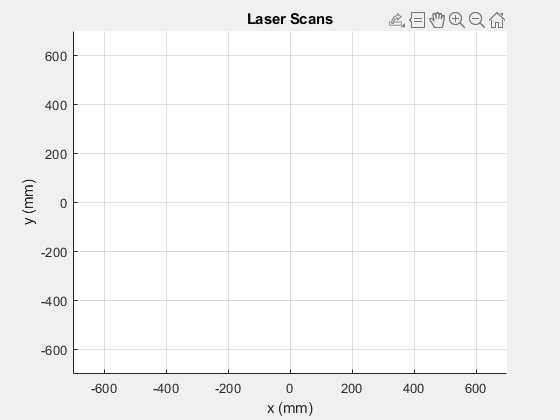

LaserPlot1.axis1=axes('parent',LaserPlot1.figure,'units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1,'on')
LaserPlot1.axis1.Title.String = 'Laser Scans';
LaserPlot1.XLabel.String = 'X Axis';
LaserPlot1.YLabel.String = 'Y Axis';
% create a primative line object to use plotting lidar data
% XData and YData
laserRange = line('Parent',LaserPlot1.axis1,'XData',[],'YData',[],'LineStyle','none',...
    'marker','.','color','b','LineWidth',2);
grid on 
range = 700;
axis([-range range -range range])
xlabel('x (mm)')
ylabel('y (mm)')

disp('Laser scan figure set');

Laser scan figure set


## Sample and Visualize Data 

Read Lidar over USB port, parse data, create a plot of data in a 60 sec continuous loop, use CTRL-c to stop early.

**NOTE: Please don't pause and leave this section of the code, as it needs to complete and then go through a clean shuttdown in next section to avoid jamming the communication link to the Lidar **

Note: Please download the two suport Matlab functions FunRoboLidarScan.m and decodeSCIP.m from Canvas and then place them in the wokring folder with this code before proceeeding. 

disp('Read and Plot Lidar Data, type and hold ctrl-c to stop')

Read and Plot Lidar Data, type and hold ctrl-c to stop


angles = (-120:240/682:120-240/682)*pi/180; % Convert Sensor steps to angles for plotting 
% angles = angles(541:666);
tStart = tic;                                       % start experiment timer
iscan = 1;
while(iscan == 1)                                    % continuous loop, type and hold cntl-c to break
    [A] = FunRoboLidarScan(lidar);                  % actual lidar scan range data sored in [A]
    %A = A(541:666);
    laserRange.XData = A.*cos(angles);              % Use trig to find x-coord of range
    laserRange.YData = A.*sin(angles);              % Use trig to find y-coord of rangematlab:matlab.internal.language.commandline.executeCode('cd ''C:\Users\busui\OneDrive - Olin College of Engineering\Desktop\FunRobo\STA Lab''')
    distance_to_object = vecnorm([laserRange.XData; laserRange.YData]);
    distance_threshold = 914.4; % mm 
    drawnow                                         % will draw laserRange in open Laser Scan window
    pause(2)                                      % pause to allow serial communcations to keep up
    tElapsed = toc(tStart);                         % measure time (in sec) since start of experiment
    ang_step = 1;
    max_range =  4000; % mm
    while ang_step < length(angles)
        if distance_to_object(ang_step) < max_range && distance_to_object(ang_step) < distance_threshold && distance_to_object(ang_step) > 0
            %disp('There is an obstacle near by');
            len = id_target(ang_step,distance_to_object,angles);
            ang_step = ang_step + len;
        end
        ang_step = ang_step + 1;
    end 
        
%     maxHoleLen = 0;
%     maxStartAngle = 0; 
%     maxEndAngle = 0; 
    % drawnow -updates figures and processes any pending callbacks.
    % Use this command if you modify graphics objects and want to see the
    % updates on the screen immedicately. Use here to update laser range
    % draws
    if(tElapsed > 600)                               % is experiment goes too long stop sample loop
        iscan = 0;
    end
end 

    "Target found between angles "    "-85.1613"    " & "    "-78.827"

    18

    "Target found between angles "    "-74.2522"    " & "    "-67.2141"

    20

    "Target found between angles "    "-65.4545"    " & "    "-56.6569"

    25

    "Target found between angles "    "-49.2669"    " & "    "-35.8944"

    38

    "Target found between angles "    "-34.4868"    " & "    "-24.2815"

    29

    "Target found between angles "    "-15.4839"    " & "    "25.6891"

   117

    "Target found between angles "    "29.5601"    " & "    "33.783"

    12

    "Target found between angles "    "35.8944"    " & "    "90.7918"

   156

    "Target found between angles "    "111.5543"    " & "    "119.6481"

    23

    "Target found between angles "    "-65.4545"    " & "    "-56.6569"

    25

    "Target found between angles "    "-49.2669"    " & "    "-35.8944"

    38

    "Target found between angles "    "-15.4839"    " & "    "25.6891"

   117

    "Target found between angles "  

% ang = 1;
% while ang < 127
%     if distance_to_object(1,ang) > hole_threshold
%         [len, startAngle, endAngle] = findHole(ang,distance_to_object,angles);
%         if len > maxHoleLen
%             maxHoleLen = len;
%             maxStartAngle = startAngle; 
%             maxEndAngle = endAngle;
%             ang = ang + len;
%         end
%     else
%         %findTarget(ang,distance_to_object,angles);
%     end 
%     ang = ang + 1;
% end
% disp("Largest hole found between " + maxStartAngle + " degrees and " + maxEndAngle + " degrees.")
disp('Lidar scan ended');


## Disconnect Lidar and cleanly close USB serial link 

Please always run this section before exiting this mlx file. Failing to do so will leave USB link open and prevent you from attaching to Lidar for any follow on work. To clear the serial jam this causes, you will need to shut down Matlab, unplug lidar and reboot your laptop. 

***************PLEASE ALWAYS RUN THIS LIDAR DISCONNECT SECTION********************

fprintf(lidar,'QT'); % Writes the string quit to the lidar 
fclose(lidar); % disconnects lidar obj from serial port object 
clear lidar; % clear lidar obj from memory 
warning('on'); % Turn Matlab warnings back on 
disp('program ended');

function [len, startAngle, endAngle] = find_hole(start_index,distance_to_object,angles) 
    % distance is an array of distances corresponding to each point -
    % points are read left to right 
    stillHole = true;          
    tolerance = 50;
    index = start_index;
    last_index = 126;
    while index < length(distance_to_object)
        if start_index > 1
            difference = distance_to_object(1,index) - distance_to_object(1,index - 1);
            if abs(difference) > tolerance
                last_index = index - 1;
                stillHole = false;
            end    
        else
            start_index = start_index + 1;
        end 
        index = index + 1;
    end 
    startAngle = rad2deg(angles(start_index));
    endAngle = rad2deg(angles(last_index));
    len = last_index - start_index;
    if len > 10
        disp(["Hole found between angles ", startAngle, " & ", endAngle])
        id_target(last_index,distance_to_object,angles);
    end 
end
function len = id_target(start_index,distance_to_object,angles)
    % distance is an array of distances corresponding to each point -
    % points are read left to right 
    stillTarget = true;          
    tolerance = 500;
    minDistance = 1000;
    targetIndex = start_index + 5;
    last_index = length(distance_to_object);
    blueTarget = 55; 
    yellowTarget = 47; 
    whiteTarget = 46;
    redTarget = 38;
    greenTarget = 31;
    while targetIndex < length(distance_to_object) && stillTarget == true
        if targetIndex > 1
            current_target_distance = distance_to_object(1,targetIndex);
            target_difference = current_target_distance - distance_to_object(1,targetIndex - 1);
            if abs(target_difference) > tolerance
                last_index = targetIndex - 1;
                stillTarget = false;
            end    
        else
            start_index = start_index + 1;
        end 
        if current_target_distance < minDistance
            minDistance = current_target_distance;
        end
        targetIndex = targetIndex + 1;
    end 
    startAngle = rad2deg(angles(start_index));
    endAngle = rad2deg(angles(last_index));
    len = last_index - start_index;
    if len > 6
        disp(["Target found between angles ", startAngle, " & ", endAngle])
        disp(len) 
    end 
%     if len >= blueTarget
%         disp("Blue target found " + minDistance + "mm at " + startAngle + " to " + endAngle);
%     elseif len >= yellowTarget
%         disp("Yellow target found " + minDistance + "mm at " + startAngle + " to " + endAngle);
%     elseif len >= whiteTarget
%         disp("White target found " + minDistance + "mm at " + startAngle + " to " + endAngle);
%     elseif len >= redTarget
%         disp("Red target found " + minDistance + "mm at " + startAngle + " to " + endAngle);
%     elseif len >= greenTarget
%         disp("Green target found " + minDistance + "mm at " + startAngle + " to " + endAngle);
%     end 
end 